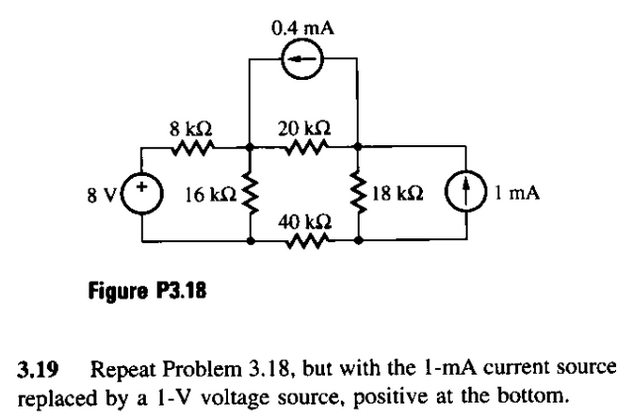

Nos piden que reemplacemos la fuente de corriente de 1mA por una fuente de tension de 1V, redibujamos el circuito con nuestro nodo de referencia:

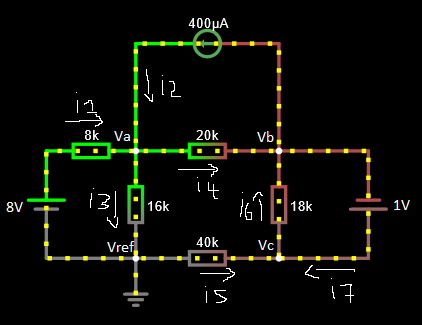

tenemos tres incognitas por lo tanto tres ecuaciones:

clc, clear, close all

Vref = 0;
Vf = 8;
syms Va Vb Vc

Definimos las correintes que pasan en cada elemento


i1 = (Vf-Va)/8*1e3;

i2 = 0.4*1e-3;

i3 = Va/16*1e3;

i4 = (Va-Vb)/20*1e3;

i5 = -Vc/40*1e3;

i6 = (Vc-Vb)/18*1e3;

i7 = i5-i6;


Definidas las correintes planteamos las ecuaciones para cada nodo, teneindo en cuenta que para la fuente de tension de 1V que noestá conectada directamente a tierra, se debe hacer un supernodo, para ello, primero definimos la ecuacion de supernodo:

sp = (Vc - Vb == 1);
%se puede expresar de la siguiente forma:
Vc = 1+Vb

$$Vc = \mathrm{Vb}+1$$

Y luego definimos las ecuaciones de nodo, cortocirtuitando la fuente de tension de 1V y tomando Vb y Vc como un solo nodo

n_a = simplify(((8-Va)/8000)-(Va/16000)-((Va-Vb)/20000)== -0.4e-3)

$$n\_a = 19\,\mathrm{Va}=4\,\mathrm{Vb}+112$$

n_bc = simplify(((-Vc)/40000)+((Va-Vb)/20000) == 0.4e-3);
%donde se puede reemplazar Vc para quedar con un sistema de ecuaciones 2x2
n_bc = 2*Va -3*Vb == 17

$$n\_bc = 2\,\mathrm{Va}-3\,\mathrm{Vb}=17$$

resolvemos el sistema 2x2:

m = [19 -4; 2 -3];
n = [112;17];
h = m\n;
Va = h(1,1)

Va = 5.4694

Vb = h(2,1)

Vb = -2.0204

Vc = Vb+1

Vc = -1.0204

Donde finalmente encontramos los potenciales en cada nodo, lo verificamos en el simulador: